### PATHS & Variables

EEGBASEPATH = './eeg';           % Find EEG files here
WAVBASEPATH = './audio';         % Find AUDIO wav files here 
MATBASEPATH = '.';               % Save preprocessed data files here
TARGET_FS = 64;

### Choosing subject and trial

ss = 1;     % subject
tt = 2;     % trial

### Loading files

% Load only expinfo from the subject's file
% subject_file = fullfile(EEGBASEPATH, 'S1.mat');

subject_file = fullfile(EEGBASEPATH,['S' num2str(ss) '.mat']);
load(subject_file, 'expinfo');

### Determining the attended speaker and the files that were listened to

attend = expinfo.attend_mf(tt);   % 1 = male attended, 2 = female attended
male_file   = expinfo.wavfile_male{tt}

male_file = 'aske_story4_trial_1.wav'

female_file = expinfo.wavfile_female{tt}

female_file = 'marianne_story3_trial_1.wav'


if attend == 1
    disp("Attended to male speaker.")
    attended_file   = male_file;
    unattended_file = female_file;
else
    disp("Attended to female speaker.")
    attended_file   = female_file;
    unattended_file = male_file;
end

Attended to female speaker.


### Eneveloping

% Pre-processing attended speaker

data = [];
cfg = [];
cfg.wavA.dataset = fullfile(WAVBASEPATH, attended_file);
data = co_preprocessing(cfg, data);
cfg = [];

cfg.wavA.dim = 'time'; 
% main range of human speech
cfg.wavA.flow = 80; 
cfg.wavA.fhigh = 8000;

% gammatone filterbank
data = co_auditoryfilterbank(cfg, data); % splits the audio into frequency bands

% Non-Linear Compression
data.wavA{1} = abs(data.wavA{1}).^0.3;

cfg = []; 
cfg.wavA.newfs = TARGET_FS;


% ACTUAL ENVELOPING PROCESS

% Resampling
data = co_resampledata(cfg, data);
cfg = []; 
cfg.wavA.dimlabel = 'freq'; 
cfg.wavA.dim = {'freq'};

% Averaging across frequencies
data = co_dimaverage(cfg, data);

% Squeezing to remove unused dimensions
data = co_squeeze(cfg, data);

env_attended = data.wavA{1};

% Processing unattended speaker
data = [];
cfg = [];
cfg.wavA.dataset = fullfile(WAVBASEPATH, unattended_file);
data = co_preprocessing(cfg, data);
cfg = [];

cfg.wavA.dim = 'time'; 
cfg.wavA.flow = 80; 
cfg.wavA.fhigh = 8000;

data = co_auditoryfilterbank(cfg, data);
data.wavA{1} = abs(data.wavA{1}).^0.3;

cfg = []; 
cfg.wavA.newfs = TARGET_FS;

data = co_resampledata(cfg, data);
cfg = []; 
cfg.wavA.dimlabel = 'freq'; 
cfg.wavA.dim = {'freq'};

data = co_dimaverage(cfg, data);
data = co_squeeze(cfg, data);

env_unattended = data.wavA{1};

### Visualization of the Envelopes

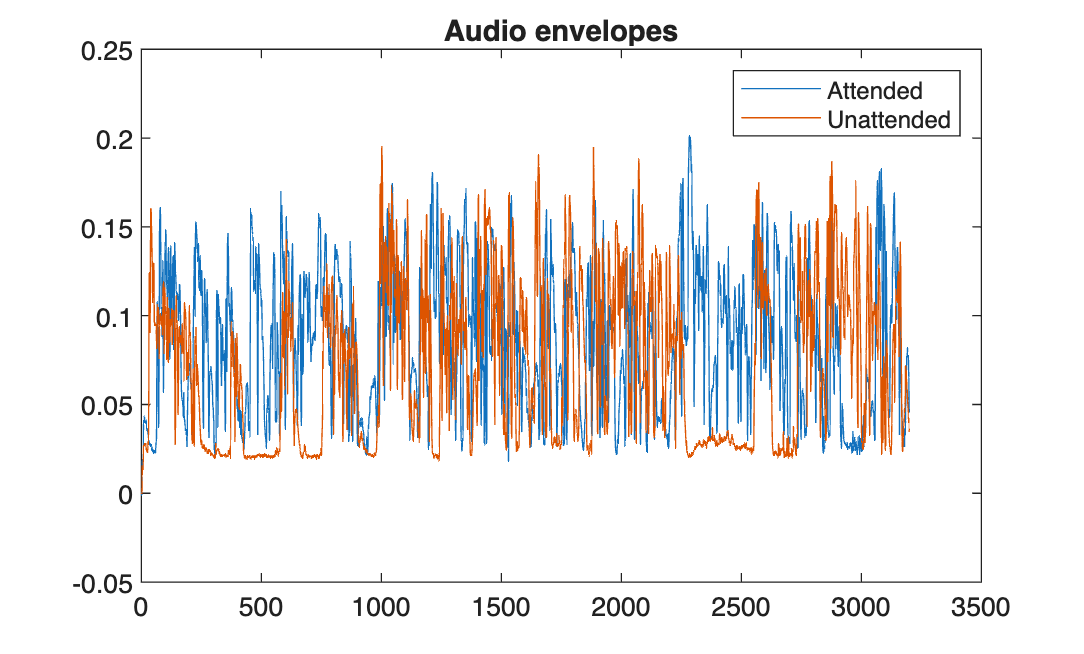

figure;
plot(env_attended); hold on;
plot(env_unattended);
legend('Attended', 'Unattended');
title('Audio envelopes');

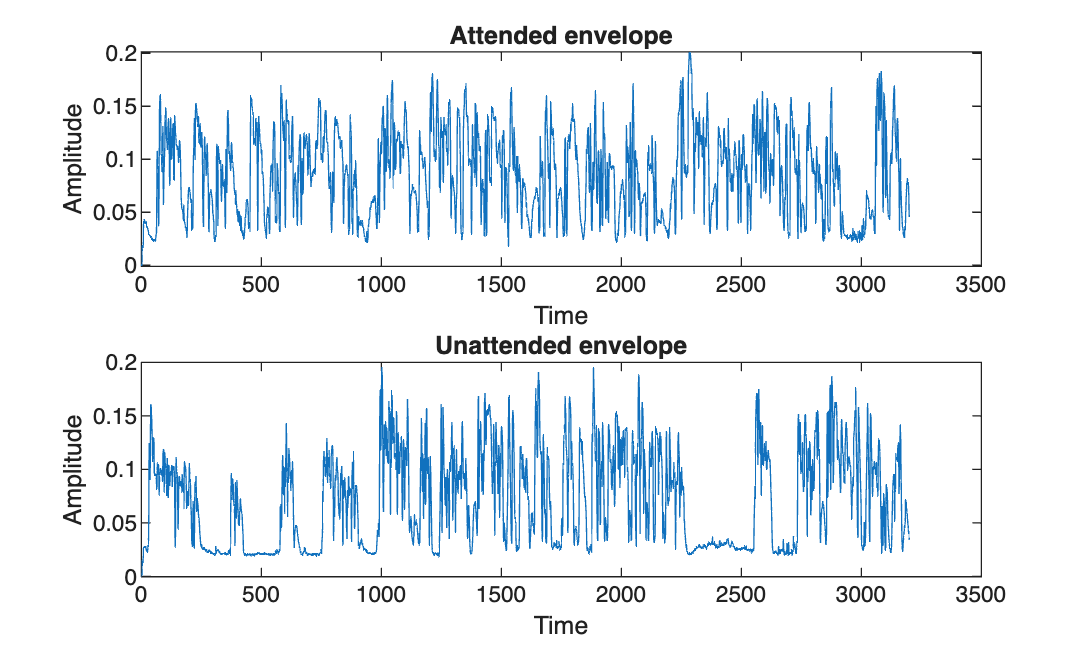


figure;
subplot(2,1,1);
plot(env_attended);
title('Attended envelope');
xlabel('Time'); ylabel('Amplitude');

subplot(2,1,2);
plot(env_unattended);
title('Unattended envelope');
xlabel('Time'); ylabel('Amplitude');

Next steps as described in the paper are:

- Bandpass the envelope between **1–10 Hz** (3rd-order Butterworth, zero phase).

- Compute the **derivative** (rate of change) of that filtered envelope.

- **Half-wave rectify** the derivative (keep only positive increases).

- Detect **local peaks** of the positive derivative → these are **peakRate events**.

- Apply a **threshold = 0.1 * σ** (σ = std of positive derivative) to keep only prominent peaks.

- Convert peak indices → times and optionally classify as *glimpsed* vs *masked* by comparing attended vs unattended envelopes at those times.

### PeakRate detection

% Bandpass 1–10 Hz, 3rd-order Butterworth
low = 1; high = 10; ord = 3;
Wn = [low high] / (TARGET_FS/2);      % normalize by Nyquist
[b,a] = butter(ord, Wn, 'bandpass');

% --- Attended ---
env_filt_att = filtfilt(b, a, double(env_attended));  % filter envelope
deriv_att = [0; diff(env_filt_att)];                 % derivative
pos_deriv_att = deriv_att; pos_deriv_att(pos_deriv_att<0)=0; % half-wave rectify

sigma_att = std(pos_deriv_att);
thresh_att = 0.1 * sigma_att;

[peakVals_att, peakLocs_att] = findpeaks(pos_deriv_att, 'MinPeakHeight', thresh_att);
times_att = (peakLocs_att-1)/TARGET_FS;

% --- Unattended ---
env_filt_unatt = filtfilt(b, a, double(env_unattended));
deriv_unatt = [0; diff(env_filt_unatt)];
pos_deriv_unatt = deriv_unatt; pos_deriv_unatt(pos_deriv_unatt<0)=0;

sigma_unatt = std(pos_deriv_unatt);
thresh_unatt = 0.1 * sigma_unatt;

[peakVals_unatt, peakLocs_unatt] = findpeaks(pos_deriv_unatt, 'MinPeakHeight', thresh_unatt);
times_unatt = (peakLocs_unatt-1)/TARGET_FS;


### Classify glimpsed vs masked at attended peaks Method 1 (Naive Method)

We just simply compare the peak values of the attended event vs the corresponding values of the unattended one:

- Filter attended and unattended envelopes 1–10 Hz.

- Computes half-wave rectified derivative → only upward changes.

- Finds peaks above 0.1·σ.

- For each attended peak, compares amplitude to unattended → `isGlimpsed` = `true` if attended louder.

isGlimpsed = env_attended(peakLocs_att) > env_unattended(peakLocs_att);

### Visualization

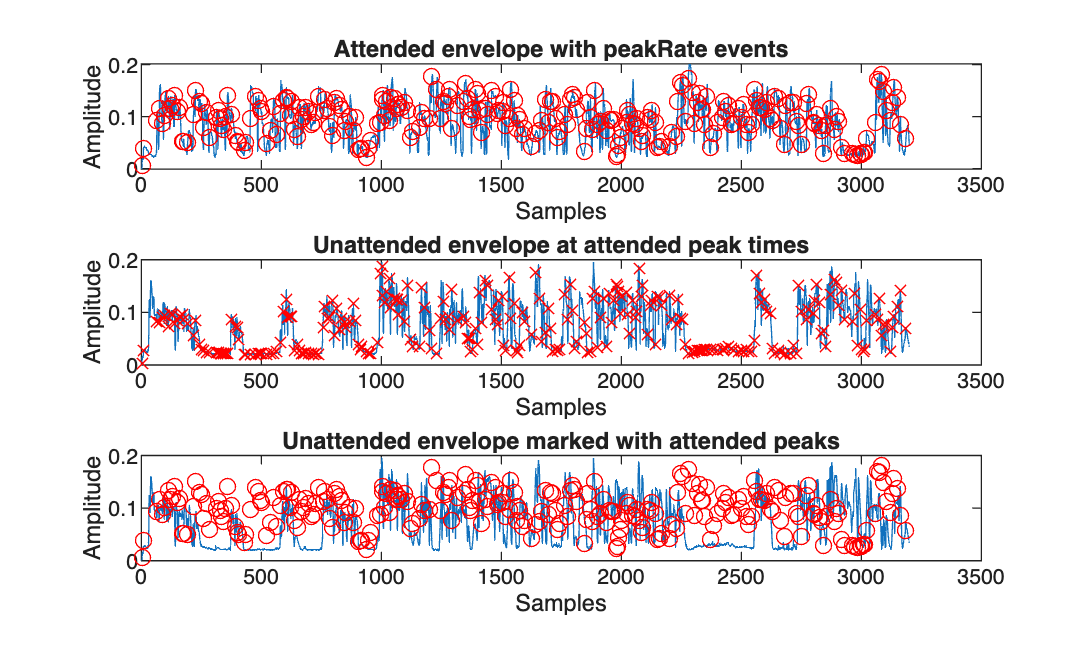

% figure;
% plot(env_attended); hold on;
% plot(env_unattended);
% plot(peakLocs_att, env_attended(peakLocs_att), 'ro');  % attended peaks
% legend('Attended', 'Unattended', 'PeakRate Attended');
% title('Audio envelopes with detected peaks');

figure;
subplot(3,1,1);
plot(env_attended); hold on;
plot(peakLocs_att, env_attended(peakLocs_att), 'ro');
title('Attended envelope with peakRate events');
xlabel('Samples'); ylabel('Amplitude');

subplot(3,1,2);
plot(env_unattended); hold on;
plot(peakLocs_att, env_unattended(peakLocs_att), 'rx');
title('Unattended envelope at attended peak times');
xlabel('Samples'); ylabel('Amplitude');

subplot(3,1,3);
plot(env_unattended); hold on;
plot(peakLocs_att, env_attended(peakLocs_att), 'ro');
title('Unattended envelope marked with attended peaks');
xlabel('Samples'); ylabel('Amplitude');

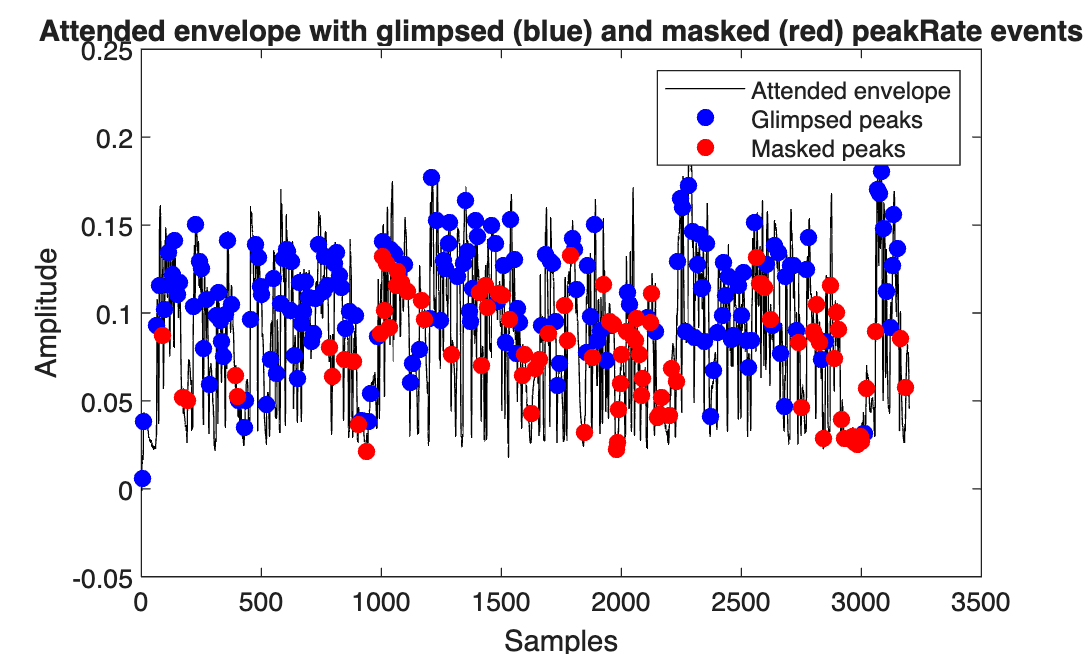



%% Prepare values for plotting
glimpse_peaks_m1 = peakLocs_att(isGlimpsed);
glimpse_vals_m1  = env_attended(glimpse_peaks_m1);

masked_peaks_m1 = peakLocs_att(~isGlimpsed);
masked_vals_m1  = env_attended(masked_peaks_m1);

%% Plot
figure;
plot(env_attended, 'k'); hold on;   % attended envelope (black)

% Glimpsed peaks in blue
plot(glimpse_peaks_m1, glimpse_vals_m1, 'bo', 'MarkerFaceColor', 'b')

% Masked peaks in red
plot(masked_peaks_m1, masked_vals_m1, 'ro', 'MarkerFaceColor', 'r')

legend('Attended envelope','Glimpsed peaks','Masked peaks')
title('Attended envelope with glimpsed (blue) and masked (red) peakRate events')
xlabel('Samples')
ylabel('Amplitude')

### Classify glimpsed vs masked at attended peaks Method 2

The paper does sth a little more complex:

- Computes a **spectrogram** of attended and unattended envelopes with safe window size.

- For each **peakRate event**:

- Extracts a ±200 ms window around the peak.

- Compares attended vs unattended magnitude with **glimpse SNR** (-4 dB).

- Computes **glimpse ratio** and **mask ratio**.

- Classifies each peak as **glimpsed** if `glimpse_ratio > 0.5`.

- Plots the ratios for sanity check.

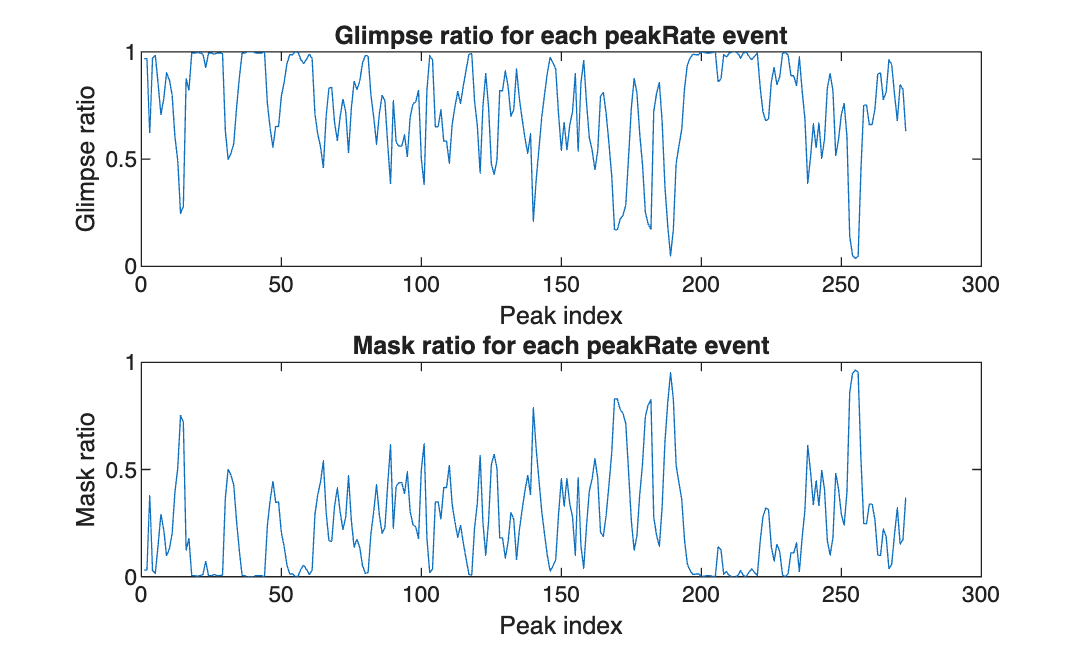

%% Glimpse vs Mask classification

% Parameters
glimpse_SNR_dB = -4;                  % SNR threshold for glimpsed vs masked
glimpse_SNR = 10^(glimpse_SNR_dB/20); % convert dB to linear scale
win_ms = 0.2;  % ±200 ms around each peak
hop_ms = 0.008; % 8 ms hop for spectrogram

% Convert to samples
win_samples = max(round(win_ms*TARGET_FS), 2); % at least 2 samples
hop_samples = max(round(hop_ms*TARGET_FS), 1); % at least 1 sample
nfft = max(256, 2^nextpow2(win_samples));

% Compute spectrograms for the whole envelope
[S_att, F, T] = spectrogram(env_attended, win_samples, floor(win_samples/2), nfft, TARGET_FS);
mag_att = abs(S_att);

[S_unatt, ~, ~] = spectrogram(env_unattended, win_samples, floor(win_samples/2), nfft, TARGET_FS);
mag_unatt = abs(S_unatt);

% Initialize glimpse/mask ratio arrays
glimpse_ratio = zeros(length(peakLocs_att),1);
mask_ratio    = zeros(length(peakLocs_att),1);

% Loop through each peakRate event
for i = 1:length(peakLocs_att)
    % Find closest time index in spectrogram
    [~, t_idx] = min(abs(T - (peakLocs_att(i)-1)/TARGET_FS));
    
    % Define window around peak (±200 ms)
    time_window = find(T >= T(t_idx)-win_ms & T <= T(t_idx)+win_ms);
    
    if isempty(time_window)
        continue
    end
    
    % Extract spectrogram segments for this window
    seg_att = mag_att(:, time_window);
    seg_unatt = mag_unatt(:, time_window);
    
    % Glimpse: attended ≥ unattended * SNR
    glimpse_mask = seg_att >= seg_unatt * glimpse_SNR;
    
    % Compute glimpse & mask ratios
    glimpse_ratio(i) = sum(glimpse_mask(:)) / numel(glimpse_mask);
    mask_ratio(i)    = 1 - glimpse_ratio(i);
end

% Decide glimpsed vs masked for each peak (example: threshold 0.5)
isGlimpsed_event = glimpse_ratio > 0.5;

%% ---------------------------
%% Visualization
%% ---------------------------
% figure;
% plot(env_attended); hold on;
% plot(env_unattended);
% plot(peakLocs_att, env_attended(peakLocs_att), 'ro');  % attended peaks
% legend('Attended', 'Unattended', 'PeakRate Attended');
% title('Audio envelopes with detected peaks');

figure;
subplot(2,1,1);
plot(glimpse_ratio);
title('Glimpse ratio for each peakRate event');
xlabel('Peak index'); ylabel('Glimpse ratio');

subplot(2,1,2);
plot(mask_ratio);
title('Mask ratio for each peakRate event');
xlabel('Peak index'); ylabel('Mask ratio');



%% Prepare values for plotting
glimpse_peaks_m2 = peakLocs_att(isGlimpsed_event);
glimpse_vals_m2  = env_attended(glimpse_peaks_m2);

masked_peaks_m2 = peakLocs_att(~isGlimpsed_event);
masked_vals_m2  = env_attended(masked_peaks_m2);

% %% Plot
% figure;
% plot(env_attended, 'k'); hold on;   % attended envelope (black)
% 
% % Glimpsed peaks in blue
% plot(glimpse_peaks_m2, glimpse_vals_m2, 'bo', 'MarkerFaceColor', 'b')
% 
% % Masked peaks in red
% plot(masked_peaks_m2, masked_vals_m2, 'ro', 'MarkerFaceColor', 'r')
% 
% legend('Attended envelope','Glimpsed peaks','Masked peaks')
% title('Attended envelope with glimpsed (blue) and masked (red) peakRate events')
% xlabel('Samples')
% ylabel('Amplitude')

### Comparing Method 1 (simple method) vs Method 2 (paper's method)

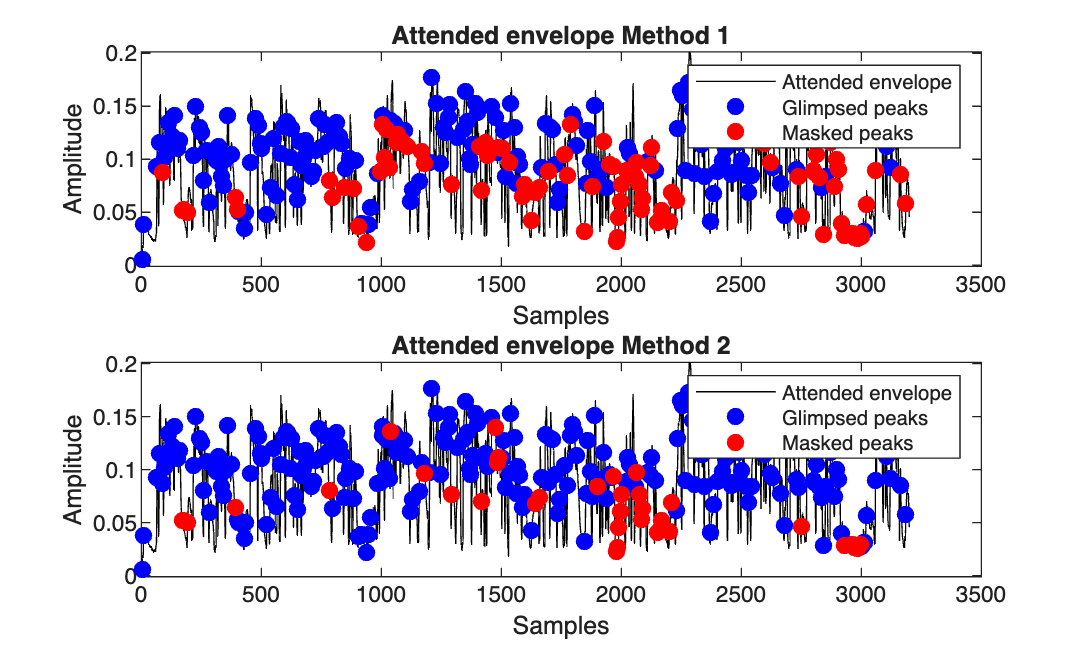

%% Plot
figure;
subplot(2,1,1);
plot(env_attended, 'k'); hold on;   % attended envelope (black)
% Glimpsed peaks in blue
plot(glimpse_peaks_m1, glimpse_vals_m1, 'bo', 'MarkerFaceColor', 'b')
% Masked peaks in red
plot(masked_peaks_m1, masked_vals_m1, 'ro', 'MarkerFaceColor', 'r')
legend('Attended envelope','Glimpsed peaks','Masked peaks')
title('Attended envelope Method 1')
xlabel('Samples')
ylabel('Amplitude')

subplot(2,1,2);
plot(env_attended, 'k'); hold on;   % attended envelope (black)
% Glimpsed peaks in blue
plot(glimpse_peaks_m2, glimpse_vals_m2, 'bo', 'MarkerFaceColor', 'b')
% Masked peaks in red
plot(masked_peaks_m2, masked_vals_m2, 'ro', 'MarkerFaceColor', 'r')
legend('Attended envelope','Glimpsed peaks','Masked peaks')
title('Attended envelope Method 2')
xlabel('Samples')
ylabel('Amplitude')